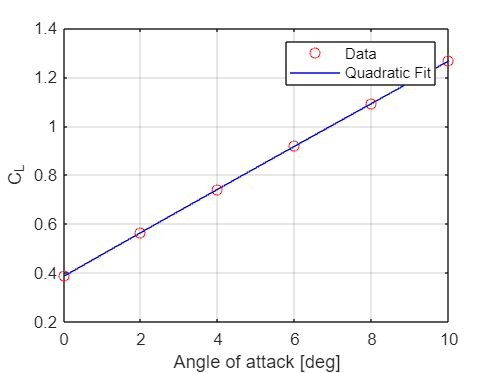

% Polynomial fitting to assist in lift, drag, and alpha coefficient
% values and approximations for more accurate results

alpha_deg = [0, 2, 4, 6, 8, 10];   % degrees
CL_values = [0.388, 0.563, 0.742, 0.920, 1.093, 1.266]; % Values taken from boeing 737-800 paper

n = 2; % order of polynomial (quadratic)
polyCoeffs = polyfit(alpha_deg, CL_values, n);  % stores [a b c]

% Use polyCoeffs instead of p
CL_fun = @(alpha) polyCoeffs(1)*alpha.^2 + polyCoeffs(2)*alpha + polyCoeffs(3);

alpha_test = 0:0.1:10;
plot(alpha_deg, CL_values, 'ro', alpha_test, CL_fun(alpha_test), 'b-');
legend('Data','Quadratic Fit');
xlabel('Angle of attack [deg]');
ylabel('C_L');
grid on;


fprintf('C_L(alpha) = %.5f * alpha^2 + %.5f * alpha + %.5f\n', ...
    polyCoeffs(1), polyCoeffs(2), polyCoeffs(3));

C_L(alpha) = -0.00015 * alpha^2 + 0.08949 * alpha + 0.38679
